A0A = 0:2:10

A0A =      0     2     4     6     8    10


U = 27.6; 
A0Ay = cosd(A0A)

A0Ay =             1      0.99939      0.99756      0.99452      0.99027      0.98481


A0Ax = sind(A0A)

A0Ax =             0     0.034899     0.069756      0.10453      0.13917      0.17365


Vx = U.*A0Ay

Vx =          27.6       27.583       27.533       27.449       27.331       27.181


Vy = U.*A0Ax

Vy =             0      0.96323       1.9253        2.885       3.8412       4.7927



                                    %  Free stream velocity m/s2
P = 1.225;                                   %  density of the fluid kg/m3             
Ch3= (0.250*0.063);
u = (1.81*10^-5);                            %  Flow speed (Velocity) m/s2
c = 0.063;                                   %  Chord length m  
Re = ((U*P*c)/(u))                           %  Reynolds number at any distance

Re =    1.1768e+05




D = [0.276975135180623, 0.274310213426368, 0.216796409767511, 0.171164501872807, 0.0471832995161496, -0.00948140613397671];
L = [0.36774580037606,  1.118048596658,    1.81167357433783,  2.58434512805947,  2.95914367531232,   3.69786182901735];
D1 = (D.*A0Ay) + (L.*A0Ax)

D1 =       0.27698      0.31316      0.34264      0.44036      0.45856      0.63279


L1 = (L.*A0Ay) - (D.*A0Ax)

L1 =       0.36775       1.1078       1.7921       2.5523       2.9238       3.6433


CL = ((L1)/(0.5*P*U^2*Ch3))                   % Lift coefficient equation Simulation        

CL =      0.050043      0.15075      0.24387      0.34732      0.39787      0.49579


CD = ((D1)/(0.5*P*U*U*Ch3))                   % Lift coefficient equation Simulation

CD =      0.037691     0.042615     0.046627     0.059925     0.062401      0.08611



format shortG
Ly = [2.089 3.2089 4.1352 4.8709 5.6896 6.1226]

Ly =         2.089       3.2089       4.1352       4.8709       5.6896       6.1226


Dx = [0.307 0.34028 0.29031 0.19673 0.012424 -0.19925]

Dx =         0.307      0.34028      0.29031      0.19673     0.012424     -0.19925


CLy = [0.53291 0.84872 1.137 1.3962 1.7054 1.9255];  % Lift force at different angle of attack N 
CDx = [0.1055    0.1530    0.1933    0.2325    0.2816    0.3116 ] % Drag force at different angle of attack N

CDx =        0.1055        0.153       0.1933       0.2325       0.2816       0.3116


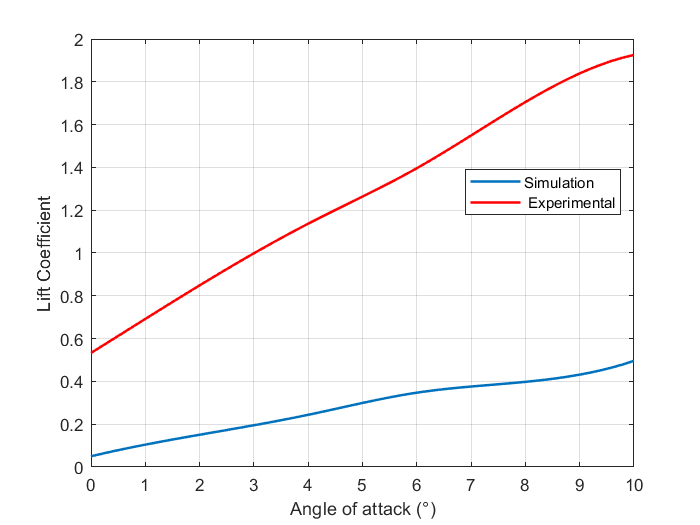





xi=linspace(min(A0A), max(A0A), 50);
xy = linspace(min(CD), max(CD), 50);
q = linspace(min(CDx), max(CDx), 50);
yispl=interp1(A0A,CL,xi,'spline');
yispL=interp1(A0A,CLy,xi,'spline');
yL=interp1(CD,CL,xy,'spline');
yX=interp1(CDx,CLy,q,'spline');

plot( xi,yispl,xi,yispL,'r-','linewidth',1.5) 
xlabel('Angle of attack (°)');
ylabel('Lift Coefficient');                         
legend ({'Simulation', ' Experimental'},'Location','best' )
grid on; 

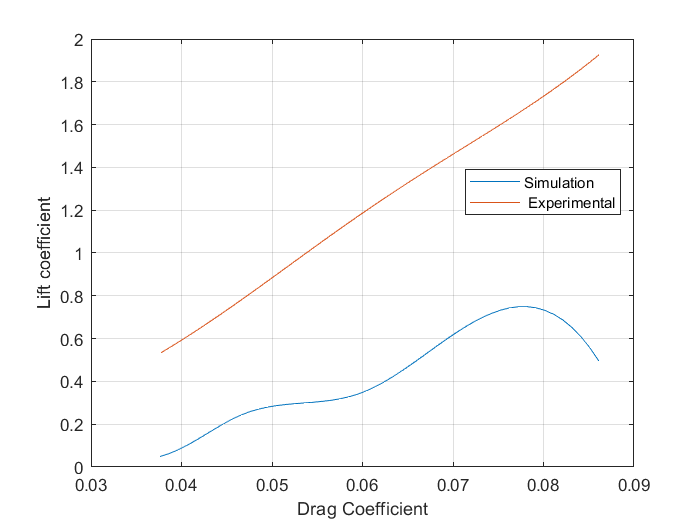




% To plot graph of CL/CD
plot (xy, yL,xy, yX)
xlabel ('Drag Coefficient')
ylabel ('Lift coefficient')
legend ({'Simulation', ' Experimental'},'Location','best' )
grid on